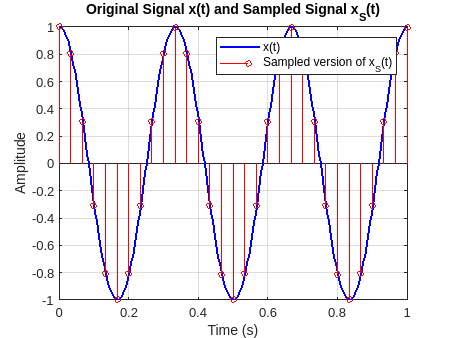

%dsp lab 3

clc; 
clear;
close all;
A = 1;          
f0 = 3;         
K = 10;         
fs = K * f0;    
Ts = 1/fs;     
M = 10;         
C = 100;        
T0 = 1/f0;              
Tmax = C * T0;           
TDelta = Ts / M;        
t = linspace(0, Tmax, round(Tmax / TDelta)); 
xt = A * cos(2 * pi * f0 * t);

data_points = length(xt);
xSt = zeros(1, data_points); 
xSt(1:M:end) = xt(1:M:end); 

figure;
plot(t, xt, 'b', 'LineWidth', 1.5); 
hold on;
stem(t(1:M:end), xSt(1:M:end), 'r', 'MarkerSize', 4);
xlabel('Time (s)'); ylabel('Amplitude');
title('Original Signal x(t) and Sampled Signal x_S(t)');
legend('x(t)', 'Sampled version of x_S(t)');
grid on;
xlim([0, 3*T0]);  

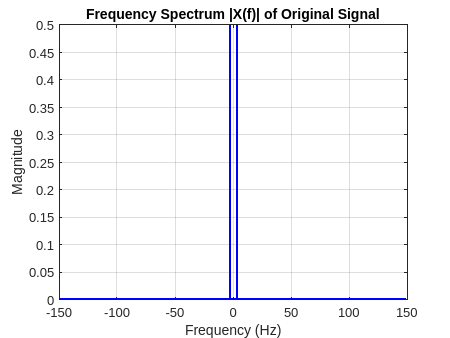


X_f = (TDelta / Tmax) * fftshift(fft(xt));  
XS_f = (1 / Tmax) * fftshift(fft(xSt));      

N = length(X_f);  %according to nyquit theorem
df = 1/Tmax;  
f_axis = (-N/2:N/2-1) * df; 

figure;
plot(f_axis, abs(X_f), 'b', 'LineWidth', 1.5);
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Frequency Spectrum |X(f)| of Original Signal');
grid on;

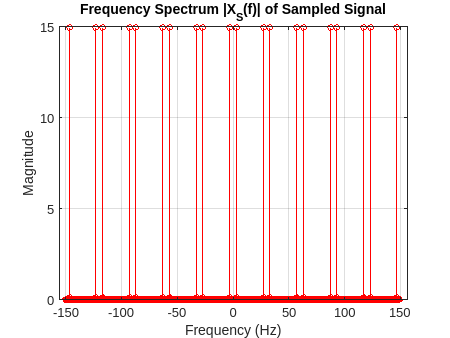


figure;
stem(f_axis, abs(XS_f), 'r', 'MarkerSize', 4);
xlabel('Frequency (Hz)'); 
ylabel('Magnitude');
title('Frequency Spectrum |X_S(f)| of Sampled Signal');
grid on;

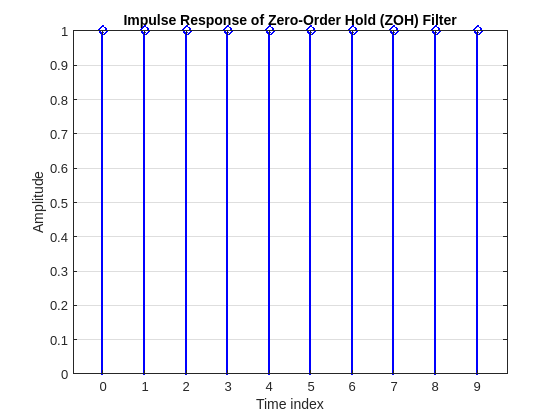

%task 2


clc; clear; close all;

A = 1;         
f0 = 3;         
K = 10;         
fs = K * f0;   
Ts = 1/fs;     

M = 10;        
C = 100;        

T0 = 1/f0;               
Tmax = C * T0;          
TDelta = Ts / M;         
t = linspace(0, Tmax, round(Tmax / TDelta));  

xt = A * cos(2 * pi * f0 * t);

data_points = length(xt);
xSt = zeros(1, data_points);
xSt(1:M:end) = xt(1:M:end); 
hzoh_t = ones(1, M); 
figure;
stem(0:M-1, hzoh_t, 'b', 'LineWidth', 1.5);
xlabel('Time index'); ylabel('Amplitude');
title('Impulse Response of Zero-Order Hold (ZOH) Filter');
grid on;

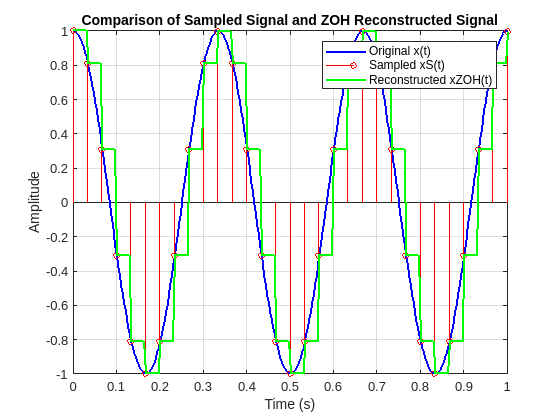


xZOH_t = filter(hzoh_t, 1, xSt);  

xZOH_t = xZOH_t / max(abs(xZOH_t)) * max(abs(xSt));

figure;
plot(t, xt, 'b', 'LineWidth', 1.5); hold on;
stem(t(1:M:end), xSt(1:M:end), 'r', 'MarkerSize', 4);
plot(t, xZOH_t, 'g', 'LineWidth', 1.5);

xlabel('Time (s)'); ylabel('Amplitude');
title('Comparison of Sampled Signal and ZOH Reconstructed Signal');
legend('Original x(t)', 'Sampled xS(t)', 'Reconstructed xZOH(t)');
grid on;
xlim([0, 3*T0]); 

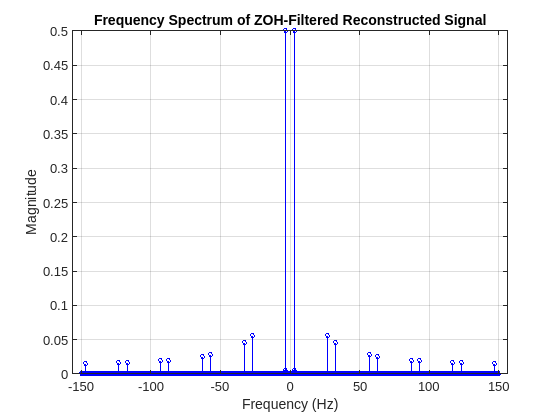


X_ZOH_f = (1/Tmax) * fftshift(fft(xZOH_t)); 

N = length(X_ZOH_f);  
df = 1/Tmax;
f_axis = (-N/2:N/2-1) * df; 

X_ZOH_f = X_ZOH_f / max(abs(X_ZOH_f)) * (A/2); 

figure;
stem(f_axis, abs(X_ZOH_f), 'b', 'MarkerSize', 3); 
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Frequency Spectrum of ZOH-Filtered Reconstructed Signal');
grid on;

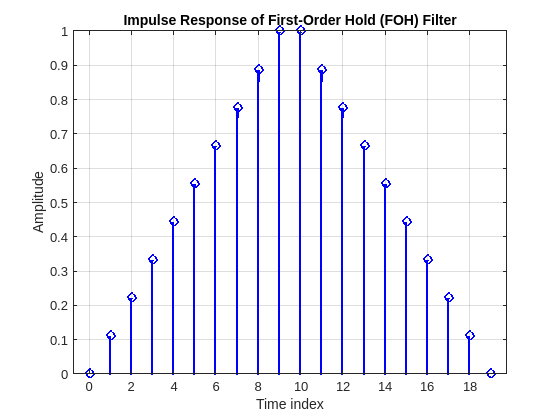

%task3:

clc; clear; close all;

A = 1;         
f0 = 3;        
K = 10;        
fs = K * f0;    
Ts = 1/fs;      

M = 10;         
C = 100;        

T0 = 1/f0;              
Tmax = C * T0;          
TDelta = Ts / M;        
t = linspace(0, Tmax, round(Tmax / TDelta)); 

xt = A * cos(2 * pi * f0 * t);

data_points = length(xt);
xSt = zeros(1, data_points); 
xSt(1:M:end) = xt(1:M:end);  

hfoh_t = [linspace(0, 1, M), linspace(1, 0, M)]; 

figure;
stem(0:length(hfoh_t)-1, hfoh_t, 'b', 'LineWidth', 1.5);
xlabel('Time index'); ylabel('Amplitude');
title('Impulse Response of First-Order Hold (FOH) Filter');
grid on;

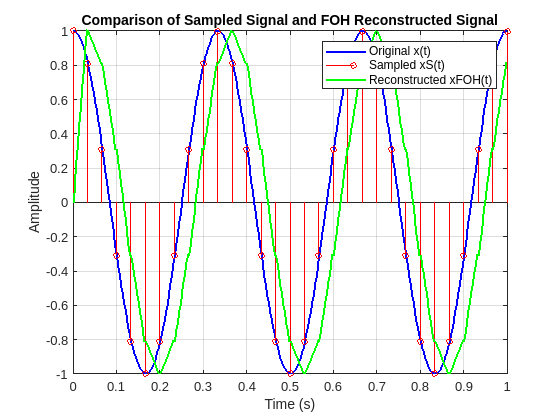


xFOH_t = filter(hfoh_t, 1, xSt); 

xFOH_t = xFOH_t / max(abs(xFOH_t)) * max(abs(xSt));

figure;
plot(t, xt, 'b', 'LineWidth', 1.5); hold on;
stem(t(1:M:end), xSt(1:M:end), 'r', 'MarkerSize', 4);
plot(t, xFOH_t, 'g', 'LineWidth', 1.5);

xlabel('Time (s)'); ylabel('Amplitude');
title('Comparison of Sampled Signal and FOH Reconstructed Signal');
legend('Original x(t)', 'Sampled xS(t)', 'Reconstructed xFOH(t)');
grid on;
xlim([0, 3*T0]); 

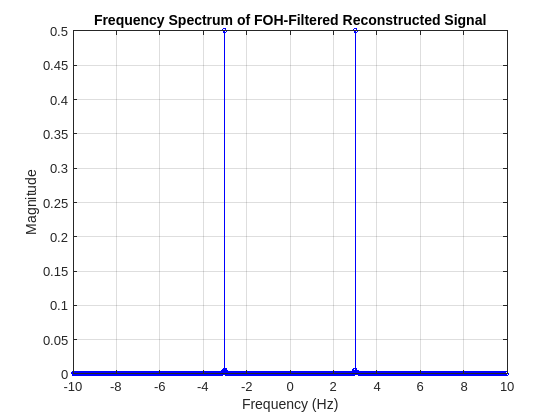


X_FOH_f = (1/Tmax) * fftshift(fft(xFOH_t));

N = length(X_FOH_f);  
df = 1/Tmax;  
f_axis = (-N/2:N/2-1) * df; 

X_FOH_f = X_FOH_f / max(abs(X_FOH_f)) * (A/2);

figure;
stem(f_axis, abs(X_FOH_f), 'b', 'MarkerSize', 3); 
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Frequency Spectrum of FOH-Filtered Reconstructed Signal');
grid on;

xlim([-10 10]);  

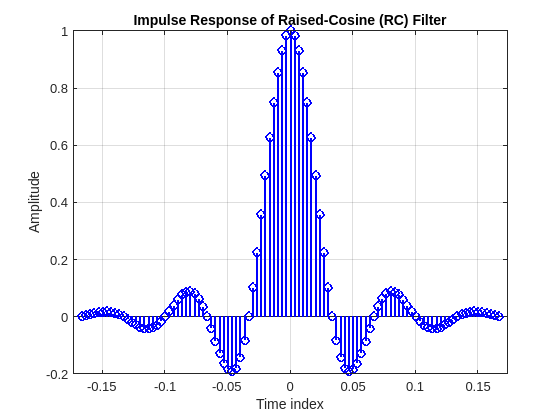



clc; clear; close all;

A = 1;         
f0 = 3;         
K = 10;        
fs = K * f0;    
Ts = 1/fs;      

M = 10;        
C = 100;        
beta = 0.25;   

T0 = 1/f0;              
Tmax = C * T0;           
TDelta = Ts / M;         
t = linspace(0, Tmax, round(Tmax / TDelta));  


xt = A * cos(2 * pi * f0 * t);

data_points = length(xt);
xSt = zeros(1, data_points); 
xSt(1:M:end) = xt(1:M:end);  

rc_t = -5*Ts:TDelta:5*Ts; 
h_rc = (sin(pi * rc_t / Ts) ./ (pi * rc_t / Ts)) .* (cos(pi * beta * rc_t / Ts) ./ (1 - (2 * beta * rc_t / Ts).^2));
h_rc(rc_t == 0) = 1; 
h_rc(abs(2 * beta * rc_t / Ts) == 1) = (pi/4) * sin(pi/(2*beta)); 

figure;
stem(rc_t, h_rc, 'b', 'LineWidth', 1.5);
xlabel('Time index'); ylabel('Amplitude');
title('Impulse Response of Raised-Cosine (RC) Filter');
grid on;

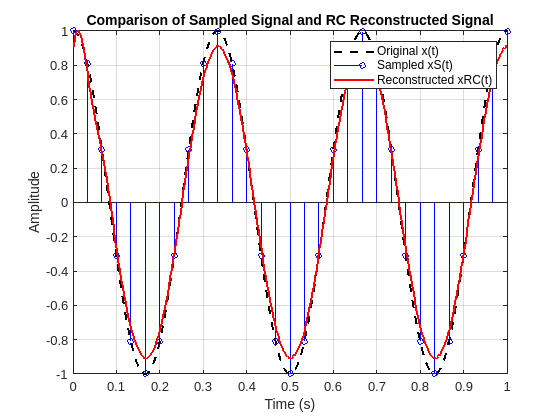


xRC_t = conv(xSt, h_rc, 'same'); 

xRC_t = xRC_t / max(abs(xRC_t)) * max(abs(xSt));

figure;
plot(t, xt, 'k--', 'LineWidth', 1.5); hold on; 
stem(t(1:M:end), xSt(1:M:end), 'b', 'MarkerSize', 4);
plot(t, xRC_t, 'r', 'LineWidth', 1.5);

xlabel('Time (s)'); ylabel('Amplitude');
title('Comparison of Sampled Signal and RC Reconstructed Signal');
legend('Original x(t)', 'Sampled xS(t)', 'Reconstructed xRC(t)');
grid on;
xlim([0, 3*T0]); 

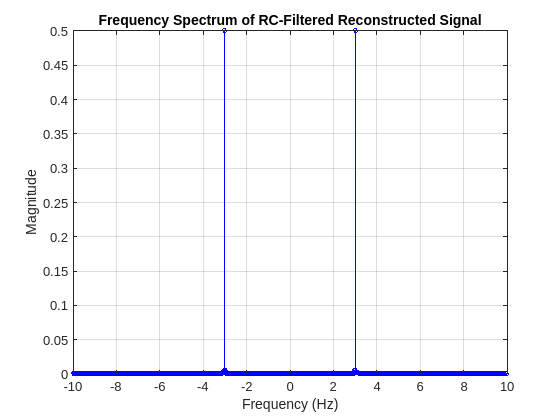


X_RC_f = (1/Tmax) * fftshift(fft(xRC_t)); 
N = length(X_RC_f);  
df = 1/Tmax;  
f_axis = (-N/2:N/2-1) * df; 

X_RC_f = X_RC_f / max(abs(X_RC_f)) * (A/2); 

figure;
stem(f_axis, abs(X_RC_f), 'b', 'MarkerSize', 3); 
xlabel('Frequency (Hz)'); ylabel('Magnitude');
title('Frequency Spectrum of RC-Filtered Reconstructed Signal');
grid on;

xlim([-10 10]);  